x=[1,3];
y=[1,4];
plot(x,y,".")
hold();

Current plot held


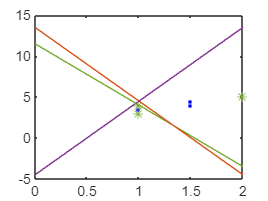

alfa=atand(3/2);
x1=sqrt((3-1)^2+(4-1)^2)/2*cosd(alfa)+1;
y1=sqrt((3-1)^2+(4-1)^2)/2*sind(alfa)+1;
plot(x1, y1, ".")
x2=10*cosd(alfa+90)+x1;
y2=10*sind(alfa+90)+y1;
x3=10*cosd(alfa-90)+x1;
y3=10*sind(alfa-90)+y1;
plot([x2,x3],[y2,y3],".")
plot([x2,x3],[y2,y3])

hold off

function dis = calcularDistancia(p1,p2)
    dis = sqrt((p1(1)-p2(1))^2+(p1(2)-p2(2))^2);
end

function [x,y] = calcularCentro(p1,p2)
    x = abs(p1(1)-p2(1))/2 + min(p1(1),p2(1));
    y = abs(p1(2)-p2(2))/2 + min(p1(2),p2(2));
end

function [alfa] = calcularAngulo(p1,p2)
    alfa = atand((p2(2)-p1(2)) / (p2(1) - p1(1))) + 90;
end

function [m,b] = calcularCoeficientes(p1,alfa)
    p2 = [p1(1)+cosd(alfa) , p1(2)+sind(alfa)];
    m = (p2(2) - p1(2)) / (p2(1) - p1(1));
    if(p2(1) == p1(1))
        m = 0;
    end
    plot(p1(1),p1(2),"b*")
    if(p2(2) == p1(2))
        b = 0;
    end
    b = p1(2) - m*p1(1);
end

puntos = [
    [1,3],
    [10,5]
    [1,4],
    [2,5],
    [7,10],
    [9,8]
    ];
vor = []


vor =

     []



plot(puntos(:,1), puntos(:,2),"g*")
hold()

Current plot held



axis([0,10,0,10])

for i= 1: size(puntos,1)
    for j=i+1: size(puntos,1)
        if (i~=j)
           [x,y] = calcularCentro(puntos(i,:), puntos(j,:));
           dis = calcularDistancia(puntos(i,:),[x,y]);
           bandera = true;
           for z=1: size(puntos,1)
               if(z~=i)
                   dis2 = calcularDistancia(puntos(z,:), [x,y]);
                   if(dis2<dis)
                       bandera = false;
                       break
                   end
               end
           end
           if(bandera)
                alfa = calcularAngulo(puntos(i,:), [x,y])
                [m, b] = calcularCoeficientes([x,y] , alfa);
                plot([0, 10],[b, 10*m+b])
           end
        end
    end
end

alfa = 180

alfa = 90

alfa = 18.4349

alfa = 135

alfa = 135

alfa = 113.1986

alfa = 45


hold off